# Descomposición espectral

load("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\S5_Estadistica101_LaVenganza.mat")


## Previs

- Stackedplot de cassini

- plotea buho (sólo un canal)

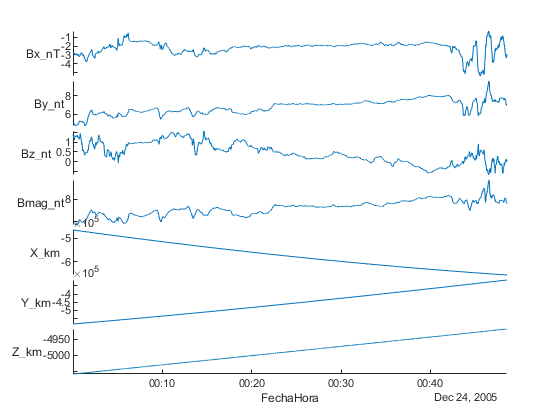

figure
stackedplot(Cassini,"XVariable",'FechaHora')

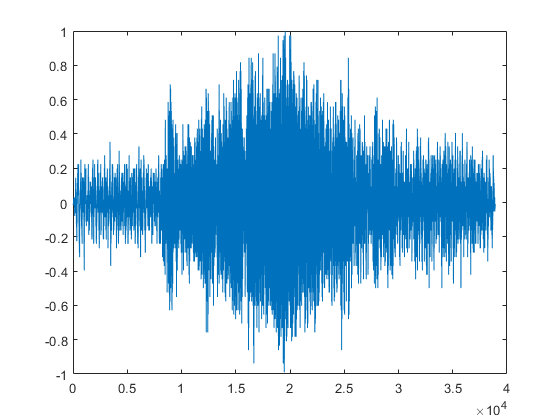



figure
plot(buho(:,1)) % (:,1) Agarra todas filas de la primer columna

%ie sólo un canal de audio


## FFT

- Craftea una función sinusoidal discreta

- Plotea

- Usa fft()

Ts=0.1; %Tiempo de sampleado
fs=1/Ts; %frecuencia de sampleado

t=0:Ts:30;
x=@(t) sin(t);

x_disc=x(t)

x_disc =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


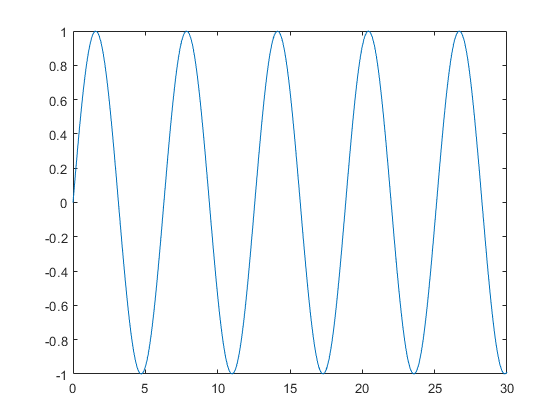


figure
plot(t,x_disc)


X=fft(x_disc)%Fast Fourier Transform fft

X = 	1.0e+02 *

   0.0796 + 0.0000i   0.0830 + 0.0211i   0.0954 + 0.0490i   0.1278 + 0.0997i   0.2518 + 0.2669i  -0.8323 - 1.1303i  -0.1267 - 0.2130i  -0.0611 - 0.1245i  -0.0370 - 0.0902i  -0.0248 - 0.0717i  -0.0175 - 0.0600i  -0.0127 - 0.0518i  -0.0094 - 0.0458i  -0.0070 - 0.0410i  -0.0051 - 0.0373i  -0.0037 - 0.0342i  -0.0026 - 0.0316i  -0.0017 - 0.0293i  -0.0009 - 0.0274i  -0.0003 - 0.0257i   0.0002 - 0.0243i   0.0007 - 0.0229i   0.0011 - 0.0217i   0.0014 - 0.0207i   0.0017 - 0.0197i   0.0019 - 0.0188i   0.0021 - 0.0180i   0.0023 - 0.0173i   0.0025 - 0.0166i   0.0027 - 0.0159i   0.0028 - 0.0153i   0.0029 - 0.0148i   0.0031 - 0.0143i   0.0032 - 0.0138i   0.0033 - 0.0133i   0.0033 - 0.0129i   0.0034 - 0.0125i   0.0035 - 0.0121i   0.0036 - 0.0117i   0.0036 - 0.0114i   0.0037 - 0.0111i   0.0037 - 0.0108i   0.0038 - 0.0105i   0.0038 - 0.0102i   0.0039 - 0.0099i   0.0039 - 0.0097i   0.0040 - 0.0094i   0.0040 - 0.0092i   0.0040 - 0.0089i   0.0041 - 0.0087i


- plotea X

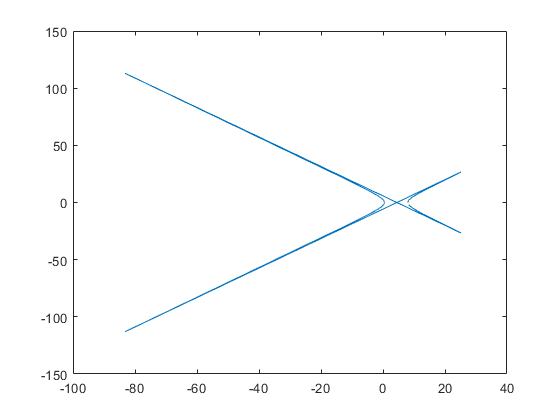

figure
plot(X) %Ojo en que X tiene valores complejos


X_mag=abs(X) %Vamos a ver la magnitud de X para que el plot sí diga algo

X_mag =     7.9564    8.5622   10.7187   16.2132   36.6895  140.3674   24.7882   13.8644    9.7515    7.5884    6.2497    5.3363    4.6710    4.1633    3.7621    3.4364    3.1663    2.9383    2.7430    2.5736    2.4253    2.2942    2.1774    2.0727    1.9782    1.8925    1.8144    1.7429    1.6772    1.6166    1.5605    1.5085    1.4600    1.4149    1.3726    1.3330    1.2958    1.2609    1.2279    1.1968    1.1674    1.1395    1.1131    1.0880    1.0642    1.0415    1.0199    0.9993    0.9796    0.9608


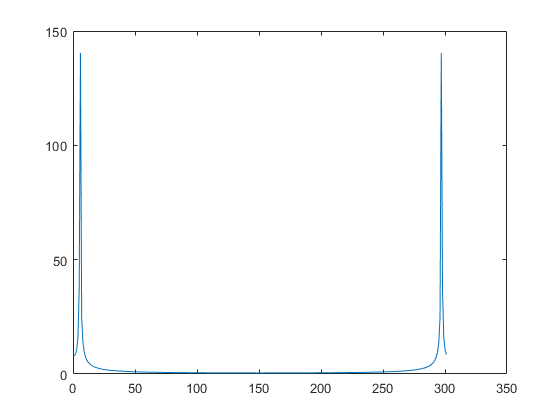


figure
plot(X_mag) %Vemos dos picos aquí :O 

%el primer pico está centrado en la frecuencia de muestreo y tiene altura
%proporcional a la amplitud de la señal


- Calculamos y ploteamos la densidad de energía

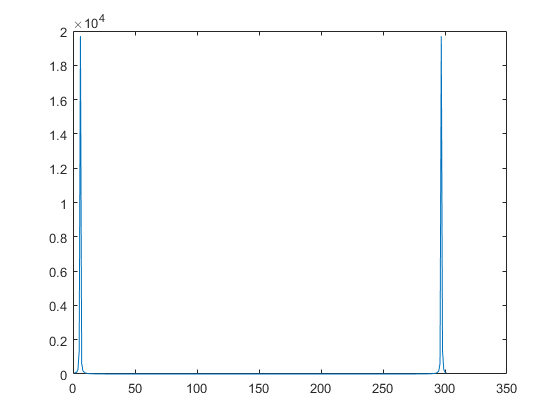

energyDens=X_mag.^2;
figure
plot(energyDens)

- Calula y plotea la densidad de potencia espectral

N=numel(x_disc); %para DPE necesito saber cuántas muestras hay
pwrDens=energyDens/(fs.*N);

pwrDens =     0.0210    0.0244    0.0382    0.0873    0.4472    6.5458    0.2041    0.0639    0.0316    0.0191    0.0130    0.0095    0.0072    0.0058    0.0047    0.0039    0.0033    0.0029    0.0025    0.0022    0.0020    0.0017    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0009    0.0008    0.0008    0.0007    0.0007    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003


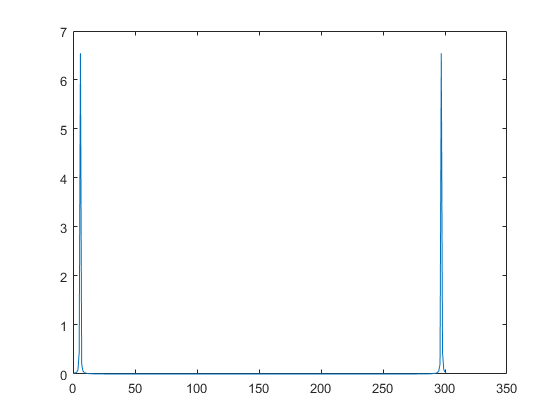


figure
plot(pwrDens)

- plotea en decibeles

- 
$$db=10log_{10}(PSD)$$


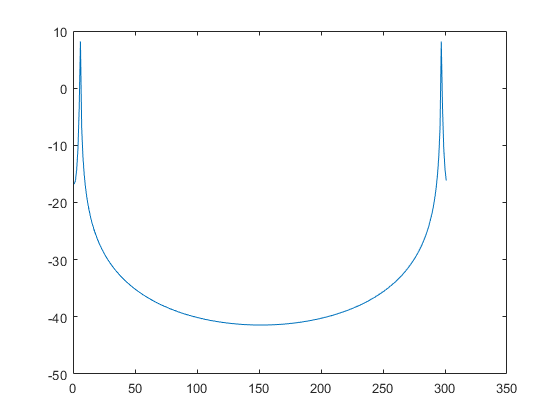

Pwrdb=10.*log10(pwrDens);
figure
plot(Pwrdb)

Tomemos la mitad de las muestras en densidad de energía y con eso calcula potencia en db

Crea la variable N_energySpectrum dónde guardes la cantidad de elementos que hay en la mitad de energyDens

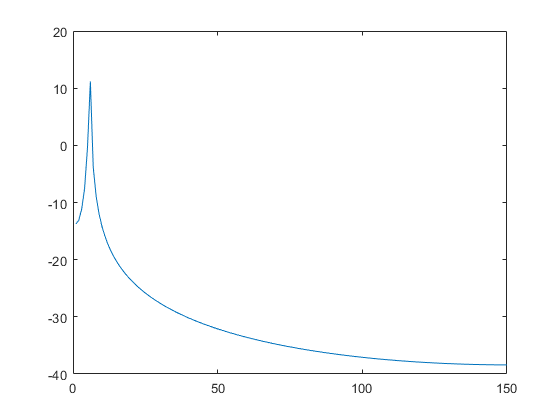

EDmichas=energyDens(1:floor(N/2));
N_energySpectrum=numel(EDmichas);

PWRDmichas=EDmichas/(fs.*N_energySpectrum);

figure
plot(10.*log10(PWRDmichas))

%por aquí creo que hay un error que me duplicaish la altura del pico
%Habrá que buscarlo


## Eje de frecuancias

fnyq=fs/2;

%Resolución en frecuencia
Df=fs/N_energySpectrum;

%Nota: con mayor fs tenemos más rango dinámico pero perdemos resolución
f=(0:N_energySpectrum-1)./N_energySpectrum .*fnyq;

f =          0    0.0333    0.0667    0.1000    0.1333    0.1667    0.2000    0.2333    0.2667    0.3000    0.3333    0.3667    0.4000    0.4333    0.4667    0.5000    0.5333    0.5667    0.6000    0.6333    0.6667    0.7000    0.7333    0.7667    0.8000    0.8333    0.8667    0.9000    0.9333    0.9667    1.0000    1.0333    1.0667    1.1000    1.1333    1.1667    1.2000    1.2333    1.2667    1.3000    1.3333    1.3667    1.4000    1.4333    1.4667    1.5000    1.5333    1.5667    1.6000    1.6333


## Contenido espectral con brillitos

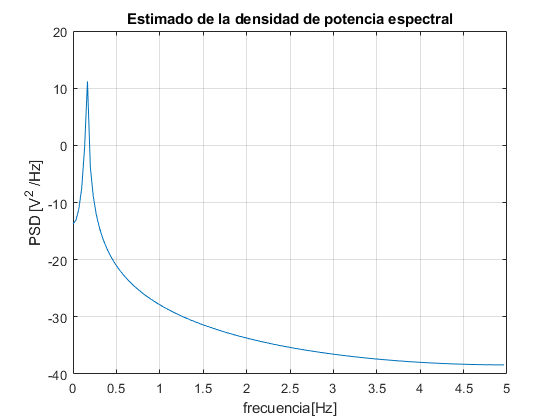

figure
plot(f,pow2db(PWRDmichas))
title("Estimado de la densidad de potencia espectral")
xlabel("frecuencia[Hz]")
ylabel("PSD [V^2 /Hz]")
grid on

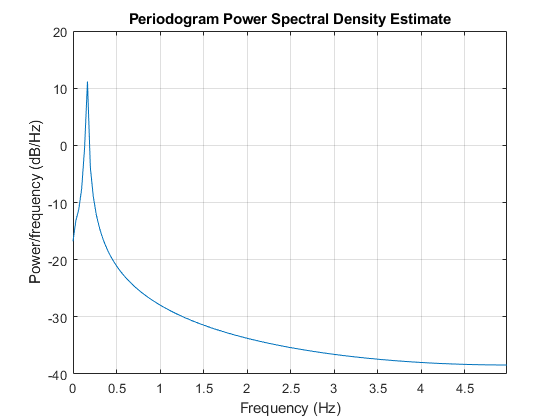


figure
periodogram(x_disc,[],N,fs)

%ylabel("Densidad de potencia [V^2/Hz]")
%xlabel("Frecuencia")
%title("Estimado de la desnidad de potencia espectral")
%Quitando los comments llegamos a lo mismo que el plot anterior


## Periodogram buho

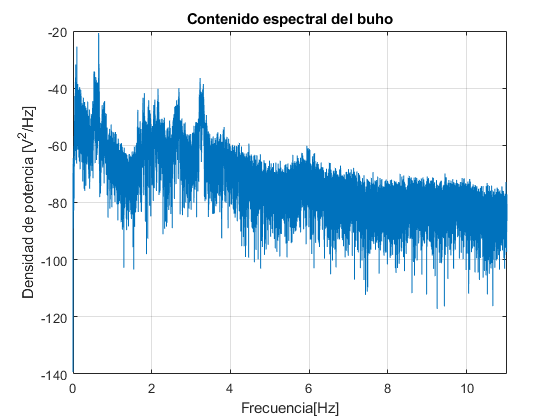

N_buho=numel(buho(:,1));
figure
periodogram(buho(:,1),[],N_buho,fs_buho)
ylabel("Densidad de potencia [V^2/Hz]")
xlabel("Frecuencia[Hz]")
title("Contenido espectral del buho")

## Saquemos datos del periodgram

[pxx,F]=periodogram(buho(:,1),[],N_buho,fs_buho)

pxx =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


F = 	1.0e+04 *

         0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003
    0.0004
    0.0005
    0.0005


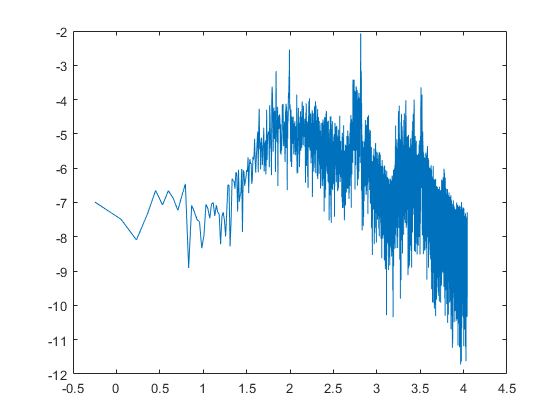


figure
plot(log10(F),log10(pxx)) %El oido reacciona en escala de log masomenos

## Espectrograma

%Favor de cuidar su RAM. Mucho cuidado
N_spect=round(N_buho/100) %cuántas divisones quieres

N_spect = 389

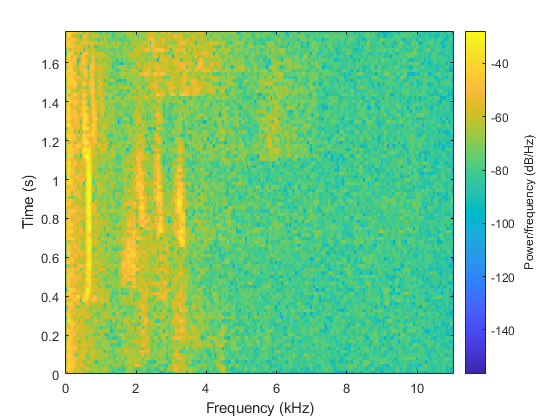


figure
spectrogram(buho(:,1),N_spect,0,[],fs_buho)